Clustering test on data

First Technique : Random Cluster Start

Section one : Load data

clear all; close all;
rawData = load('Data.mat');
X = rawData.data.X;
Y = rawData.data.Y;
%randomize data set
Idx = randperm(length(X));
X = X(Idx,:,:);
Y = Y(Idx,:);

Section two visual data based on mean of first two dimensions

%Find the mean of first two color maps  
randomPortion =  randi(ceil(length(X)/40))

randomPortion = 64

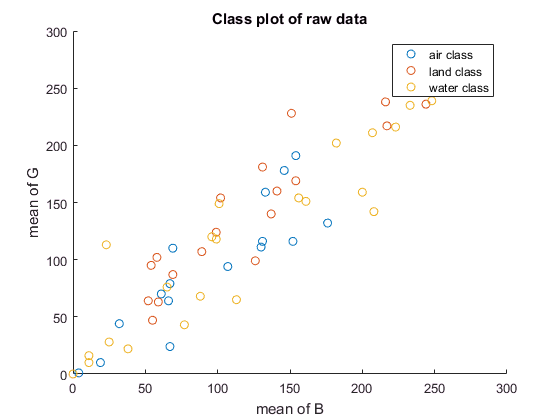

% mean_X = mean(X(1:randomPortion,randomPortion,2),2);
% mean_Y = mean(X(1:randomPortion,randomPortion,3),2);
mean_Y = X(1:randomPortion,end,2);
mean_X = X(1:randomPortion,end,3);
%Plot means of each example in their class colour
figure();
hold on;
for class = 1:3
    plot(mean_X(Y(1:randomPortion)==class),mean_Y(Y(1:randomPortion)==class),'o','MarkerSize',6,'MarkerFaceColor','none')
end
title('Class plot of raw data')
ylabel('mean of G')
xlabel('mean of B')
legend('air class','land class','water class')

Now we have the raw data ready , lets find some cluster nodes to start off the alogrithm

First we are going to spilt our images into only red , green and blue to find seperate centroids in our X array

% pass all the exmaples into the InitCentroids to find the starting centroids
numberOfClusters = 3; % only three classes present in this set
redX = X(:,:,1);
greenX = X(:,:,2);
blueX = X(:,:,3);

[ redCentroids ] = InitCentroids( redX , numberOfClusters )

The max distance to the 2 cluster is 7781.1099 
The max distance to the 3 cluster is 10925.2760 


redCentroids =     86   190   154   110    92    69    87    60    53    64    53    61    53    44    32    71   121   103    73    54    48    30    45    55    50    47    56   120   200   242   188   219   237   249   243   244   249   248   245   245   248   243   242   245   234   128   199   201   165    91
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   254   255   255   255   255   255   255   255   255   255
     5     4     3     4     4     4     3     4     5     5     7     6     5     4     4     3     2     2     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


[ greenCentroids ] = InitCentroids( greenX , numberOfClusters )

The max distance to the 2 cluster is 6850.5453 
The max distance to the 3 cluster is 10532.2183 


greenCentroids =     92    96   101   108   111   111   119   122   119    93    77    65    82    86    71    49    35    36    65    69    39    72   110   124    72    51    42    34    31    37    43    48    54    51    56    52    48    54    52    39    65   168   207   221   233   224   200   138   174   234
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
    10     9     7     6     4     4     3     3     3     2     2     3     2     3     3     3     3     3     2     2     1     2     3     3     2     3     3     3     2     2     2     2     4     2     1     2     3     4     2     3     3     4     3     5     4     4     6     8     8     9


[ blueCentroids ] = InitCentroids( blueX , numberOfClusters )

The max distance to the 2 cluster is 7179.9189 
The max distance to the 3 cluster is 11555.9301 


blueCentroids =    106    75    83    67    67    67    65    65    64    62    62    62    64    65    68    71    74    73    69    99    95   113   107   135   174   149   155   164   170   181   186   191   199   201   199   198   197   194   194   192   190   189   188   187   187   181   180   178   176   194
   253   254   255   253   251   252   253   252   252   254   252   252   254   255   255   255   255   253   252   251   251   252   254   253   253   252   252   254   253   252   252   253   251   251   251   248   254   250   230   225   238   239   207   192   221   230   157   117   131   177
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     5    13    15     6     5    15    29    30    29    26    23    20    19    16    15    13    11    10    10     5     2     3


Now lets try to assign our data with each of these clusters and see how it performs just using these random data points.

[ redAssignment ] = AssignToClosest( redX ,  redCentroids );
RedError = 1 - length(redAssignment(redAssignment == Y))/length(Y)

RedError = 0.6644

[ greenAssignment ] = AssignToClosest( greenX ,  greenCentroids );
greenError = 1 - length(greenAssignment(greenAssignment == Y))/length(Y)

greenError = 0.6669

[ blueAssignment ] = AssignToClosest( blueX ,  blueCentroids );
blueError = 1 - length(blueAssignment(blueAssignment == Y))/length(Y)

blueError = 0.6848